# Explore Overall US Covid-19 Data

Lets begin by importing the data and looking at the overall cases and deaths in the United States.

Pull from the repo or download the zip file containing the data and notes on data collection from the New York Times:

[https://github.com/nytimes/covid-19-data.git](https://github.com/nytimes/covid-19-data.git)

## Import daily cases and deaths data

Read the most recent data into MATLAB to begin exploration.

You can easily double click on the files to use the Import Tool to explore and read the data interactively. You can update data types, variable names, and other information and import it into the workspace, then generate code to repeat the steps.

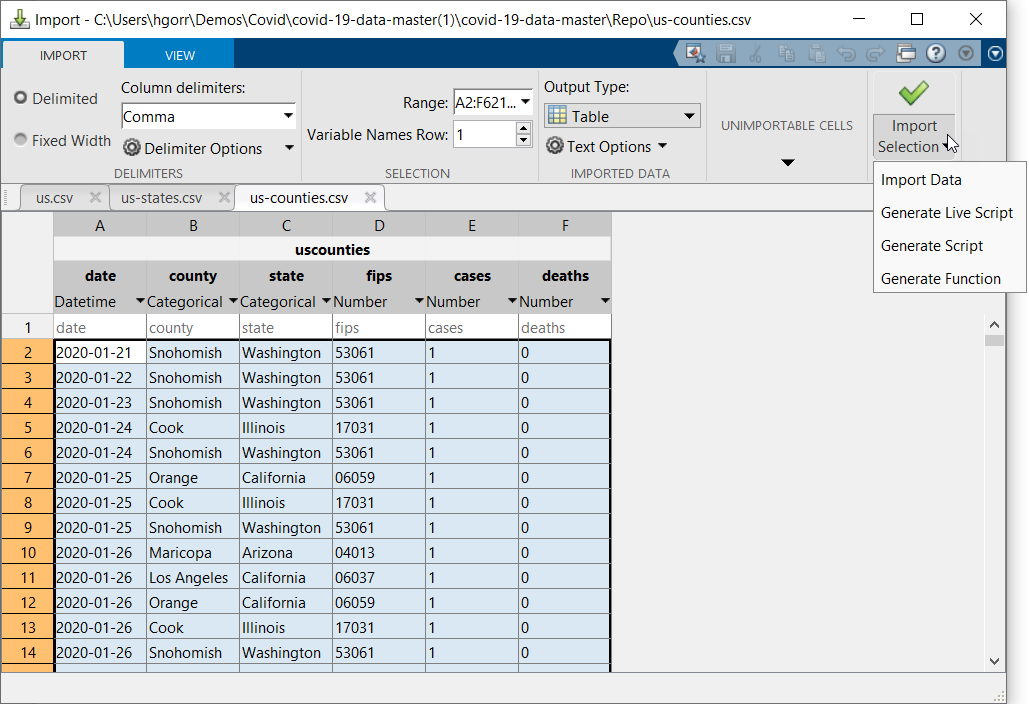

It's also easy in this case to call the function directly in this case:

us = readtimetable("us.csv")

us = 569×2 timetable
       date       cases    deaths
    __________    _____    ______
    2020-01-21      1        0   
    2020-01-22      1        0   
    2020-01-23      1        0   
    2020-01-24      2        0   
    2020-01-25      3        0   
    2020-01-26      5        0   
    2020-01-27      5        0   
    2020-01-28      5        0   
    2020-01-29      5        0   
    2020-01-30      6        0   
    2020-01-31      7        0   
    2020-02-01      8        0   
    2020-02-02     11        0   
    2020-02-03     11        0   
    2020-02-04     11        0   
    2020-02-05     12      

Examine the data. (You can double click on the variable in the workspace or in the Live Script to explore interactively)

Read the recent live data

uslive = readtimetable(fullfile("Data","live","us.csv"))

uslive = 1×6 timetable
       date         cases         deaths      confirmed_cases    confirmed_deaths    probable_cases    probable_deaths
    __________    __________    __________    _______________    ________________    ______________    _______________
    2021-08-12    3.6369e+07    6.1901e+05          NaN                NaN                NaN                NaN      

These are cumulative counts (every day has the number of all cases) and this has today's up to  date.

Add the recent data to the table (select the common variables).

us = [us; uslive(:,["cases","deaths"])];

## Visualize data over time

Let's start with plotting the cases.

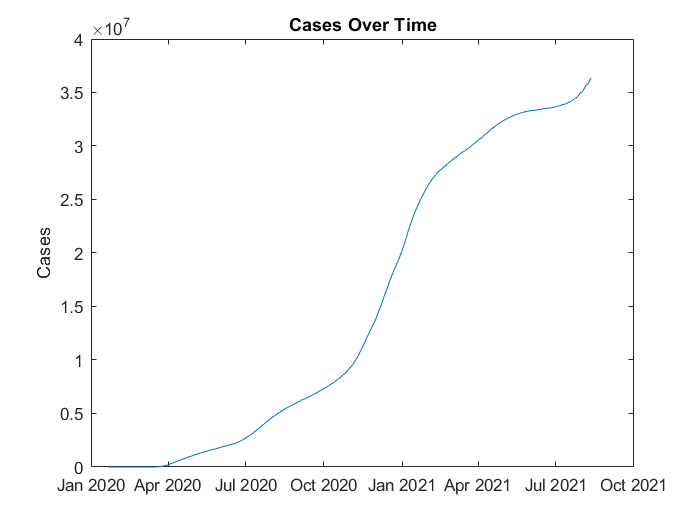

plot(us.date,us.cases)
ylabel("Cases")
title("Cases Over Time")

There are different ways to look at cases and deaths over time (line plot is classic for time series!). Others we can use for this data: stem, stair, bar, scatter, etc (explore in Plot Tools tab)

Use `comet` to show the increase dramatically in an animation!

% comet(us.cases)
% xlabel("Number of Days") 
% title("Cases Over Time")

Include deaths in the visualization. There are several ways to do this: plot the data on separate axes at first.

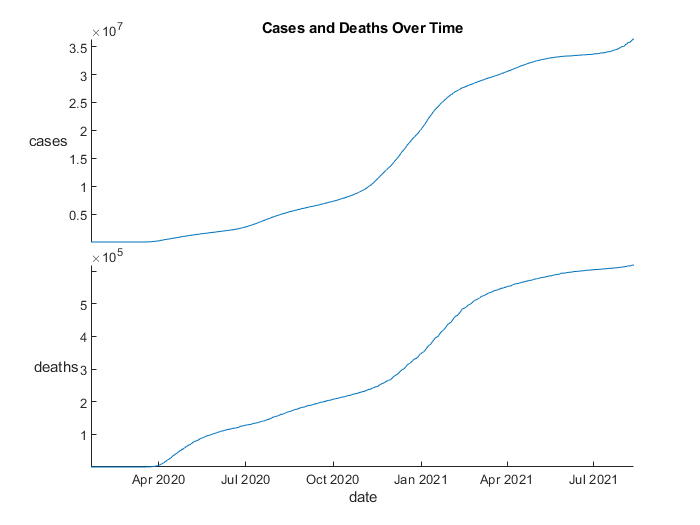

stackedplot(us);
title("Cases and Deaths Over Time")

Include cases and deaths on the same axes.

Since the numbers are so different, they need to be rescaled to see properly. We can also plot one on each axes to align them more closely and examine trends. Lets also update the case values in the visual to be more readable.

figure
yyaxis left
plot(us.date,us.cases)

Update the tick labels to show the zeros, for readability/ impact. We will do this frequently with cases, so lets create a script `updatePlotLabels` to repeat this.

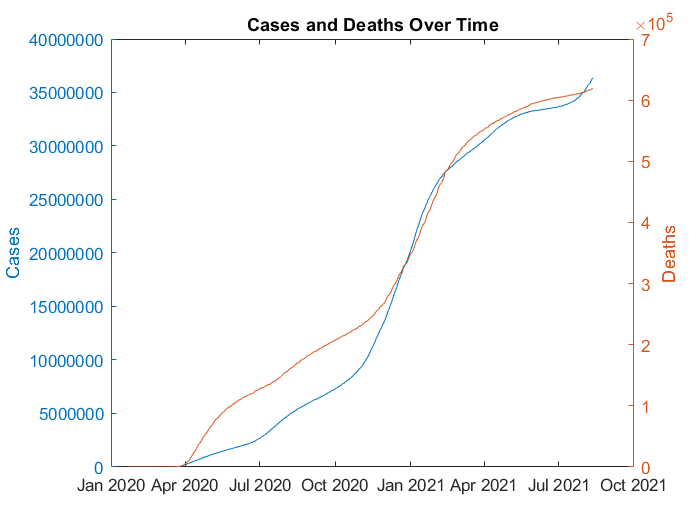

yt = yticks;
yticklabels(string(yt))
ylabel("Cases")

yyaxis right
plot(us.date,us.deaths)
% updateLabelsScript
ylabel("Deaths")
title("Cases and Deaths Over Time")

### Have holidays had an impact?

There seems to be a jump in cases around significant dates. Include public US holidays to display on the plot

holidays = datetime(["May 25, 2020"     % Memorial Day
"Jul 3, 2020"                           % Independence Day
"Sep 7, 2020"                           % Labor Day (many schools begin)
"Oct 31, 2020"                          % Halloween
"Nov 26, 2020"                          % Thanksgiving
"Dec 25, 2020"                          % Christmas
"Jan 1, 2021"                           % New Years Day
"Jan 18, 2021"                          % Martin Luther King, Jr Day
"March 17, 2021"                        % St. Patrick's Day
"May 31, 2021"                          % Memorial Day
"Jul 5, 2021"]);                        % Independence Day

Show on visual.

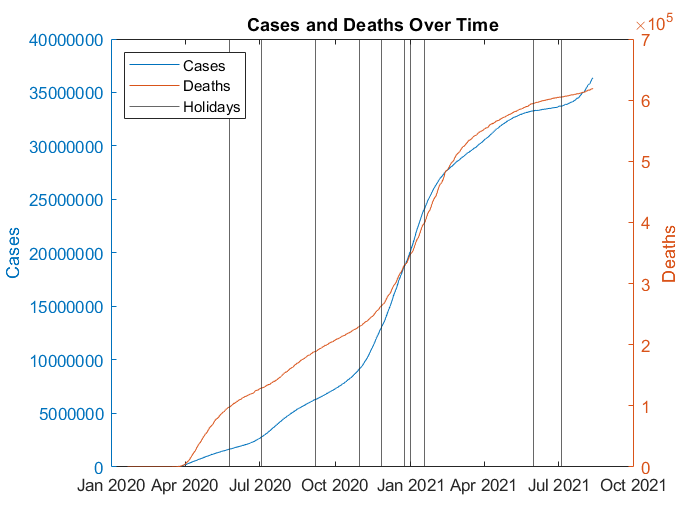

for ii = 1:length(holidays)
    xline(holidays(ii)) 
end
legend("Cases","Deaths","Holidays","Location","northwest")

We can see some possible increases around certain holidays. We would need more data to explore this further (travel data for example), but this could be important to note when communicating.

## How do the cases and deaths compare?

Plot in 3d (and zoom, pan to get the feel)

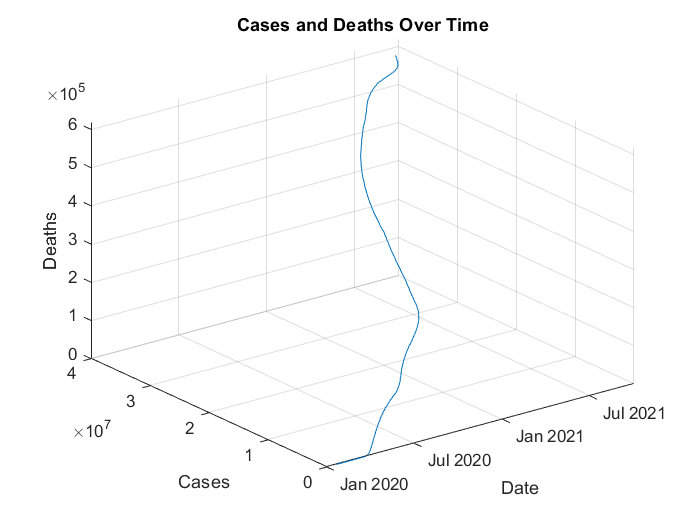

figure
plot3(us.date,us.cases,us.deaths)
xlabel("Date"); ylabel("Cases"); zlabel("Deaths")
title("Cases and Deaths Over Time")
grid on

Look at a scatter plot and include histograms

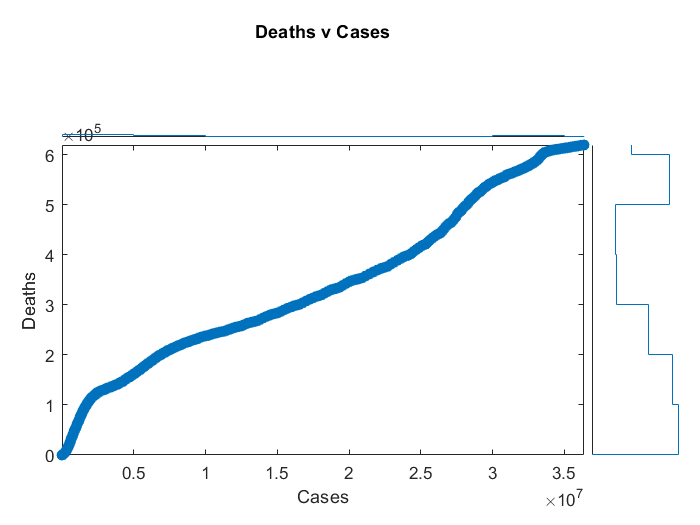

figure
scatterhistogram(us.cases,us.deaths)
xlabel("Cases"); ylabel("Deaths"); 
title("Deaths v Cases") 

You can see the slope changes over time (more deaths per cases earlier on)

There are many additional plots which could be used for multivariate data like this (explore in the Plot Gallery or in the documentation).

You might have heard of[ correlation](https://mathworks.com/help/stats/corr.html?searchHighlight=corr&s_tid=srchtitle#mw_1b19e0d5-7906-4577-a0a5-b20311da7faf), which can be useful to understand relationships. 

corr(us.cases,us.deaths)

ans = 0.9913

A perfect correlation would be 1 and a straight line in the above scatter plot. We will come back to this later when we have more variables, but clearly these values are related. 

## Which dates have had an effect?

Now, lets examine the difference in cases over time. 

We can just subtract one from the previous using `diff` (also numeric differentiation). Add this to the timetable.

d = diff(us.cases);
us.newcases = [0;d];  % align w/ times

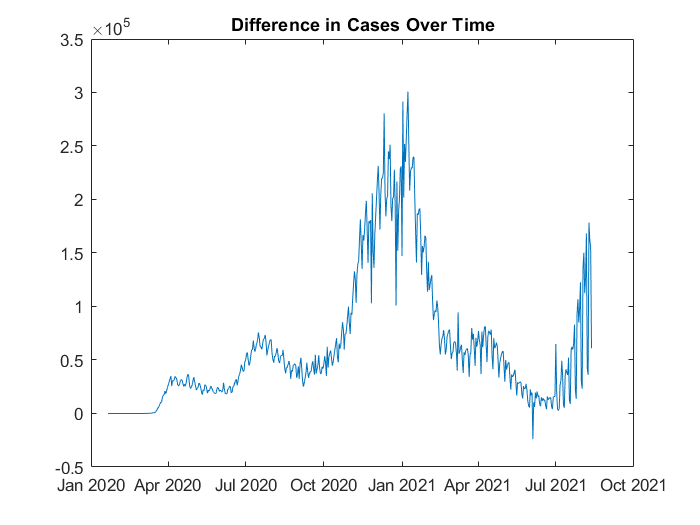

figure
plot(us.date,us.newcases)
% updateLabelsScript
title("Difference in Cases Over Time")

Let's try to visualize in another way. Examine days w biggest difference and highlight on the plot.

tk = topkrows(us,20,"newcases")

tk = 20×3 timetable
       date         cases         deaths       newcases 
    __________    __________    __________    __________
    2021-01-08    2.1989e+07     3.694e+05    3.0078e+05
    2021-01-02    2.0464e+07    3.5034e+05    2.9161e+05
    2020-12-11    1.5977e+07    2.9573e+05    2.8051e+05
    2021-01-07    2.1689e+07    3.6551e+05    2.8033e+05
    2021-01-06    2.1408e+07     3.614e+05    2.5597e+05
    2021-01-09    2.2241e+07    3.7266e+05    2.5192e+05
    2021-01-04    2.0917e+07    3.5374e+05    2.5183e+05
    2020-12-18    1.7507e+07    3.1382e+05    2.5119e+05
    2020-12-16    1.7018e+07    3.0765e+05    2.4483e+05
    2021-01-15    2.3615e+07    3.9255e+05    2

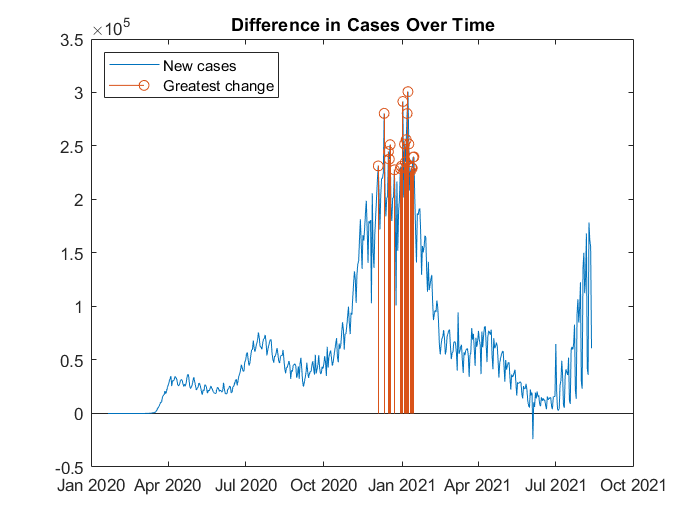

hold on
stem(tk.date,tk.newcases)
hold off
legend("New cases","Greatest change","Location","northwest")

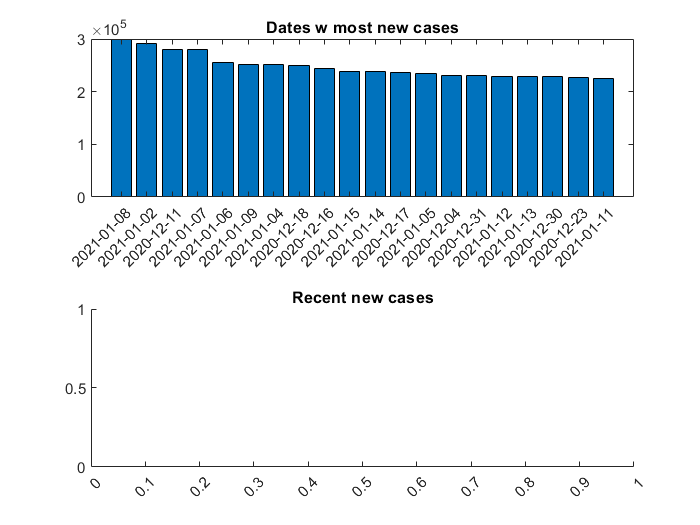

figure
tiledlayout("flow");
nexttile
bar(tk.newcases)
xticks(1:20)
xticklabels(string(tk.date))
xtickangle(45)
% updateLabelsScript
title("Dates w most new cases")
nexttile
% bar(us.date(end-19:end),us.newcases(end-19:end))
xtickangle(45)
title("Recent new cases")

% updateLabelsScript

### How do the totals by week, month compare?

Let's look at the totals by month.

byMonth = retime(us,"monthly","lastvalue")

byMonth = 20×3 timetable
       date         cases         deaths       newcases 
    __________    __________    __________    __________
    2020-01-01             7             0             1
    2020-02-01            70             1             5
    2020-03-01    1.8846e+05          4304         24506
    2020-04-01    1.0758e+06         63140         30357
    2020-05-01    1.7993e+06    1.0438e+05         20634
    2020-06-01    2.6533e+06    1.2746e+05         48389
    2020-07-01    4.5717e+06    1.5386e+05         69088
    2020-08-01    6.0455e+06    1.8347e+05         36487
    2020-09-01    7.2627e+06    2.0685e+05         42058
    2020-10-01     9.209e+06    2.3051e+05

Get the totals by week as well. Use the Retime Live Editor Task to experiment w/ different methods. 

% Retime timetable
byWeek = retime(us,'regular','lastvalue','TimeStep',calweeks(1));

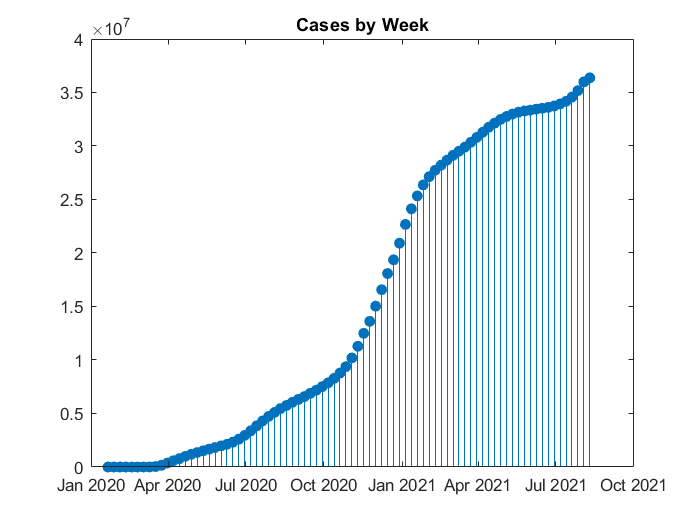

figure
stem(byWeek.date,byWeek.cases,"filled")
% updateLabelsScript
title("Cases by Week")

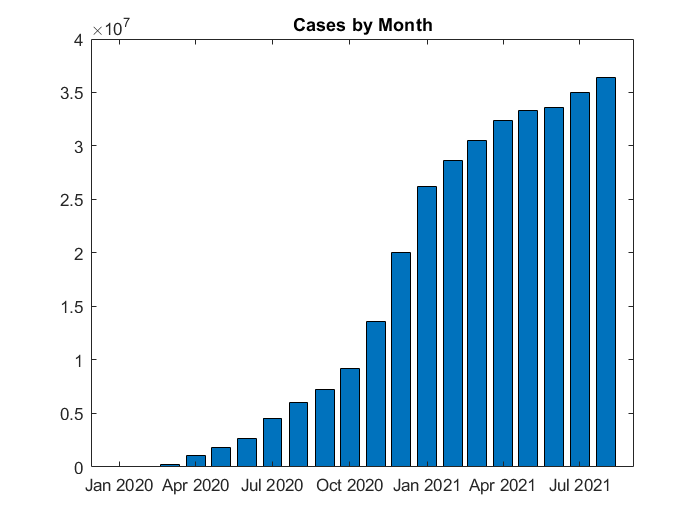

bar(byMonth.date,byMonth.cases)
% updateLabelsScript
title("Cases by Month")

Show the difference on the same visual

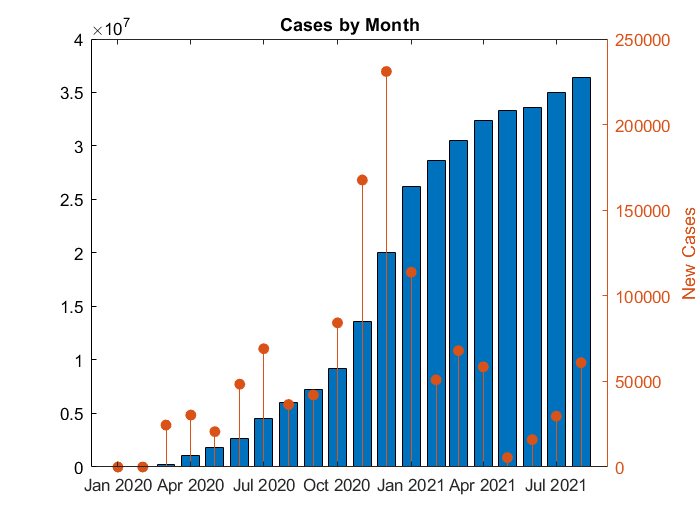

yyaxis right
stem(byMonth.date,byMonth.newcases,"filled")
updateLabelsScript
ylabel("New Cases")

## What trends are present?

Let's explore some different types of trends, starting with moving trends. We could use the Live Editor Tasks to explore the changepoints, outliers, detrend, and smooth the data - and others which can be helpful for timeseries data.

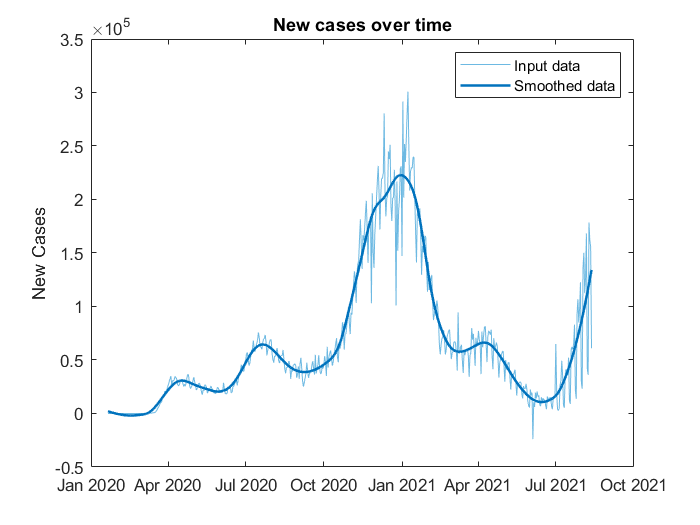

% Smooth input data
smoothedData = smoothdata(us.newcases,'loess','SmoothingFactor',0.25,...
    'SamplePoints',us.date);

% Display results
clf
plot(us.date,us.newcases,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(us.date,smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend
ylabel("New Cases")
title("New cases over time")

Try detrending the overall case numbers.

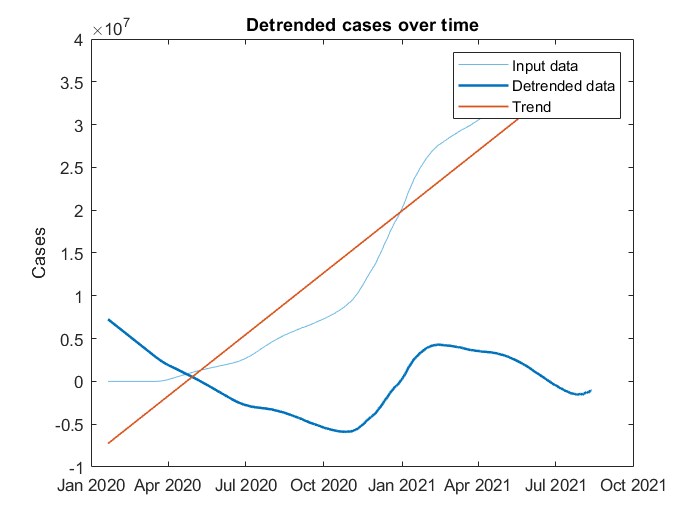

% Remove trend from data
detrendedData = detrend(us.cases,'SamplePoints',us.date);

% Display results
clf
plot(us.date,us.cases,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(us.date,detrendedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(us.date,us.cases-detrendedData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend
ylabel("Cases")
title("Detrended cases over time")

This seems interesting, the trend looks pretty linear overall except for recently, where it really deviates. 

Let's explore additional trends and possible predictive models.

## Save updated data

save Data/usData us 

## Next steps

Next, we'll explore and use predictive models to understand possible trends.

edit PredictOverallCases.mlx
edit ExploreByLocation.mlx